##  ECE 537 : Assignment 5

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

**Task 1: **Use the methods you created in Exercise 1 to create a 3-dimensional data set consisting of 5 Gaussian classes, with arbitrary means and covariances, with the following number of samples drawn from each class: Class A 750,000 Class B 190,000 Class C 45,000 Class D 12,000 Class E 3,000

Your data should be constructed such that all of the classes retain significant overlaps within one or two standard deviations of their means

Solution:

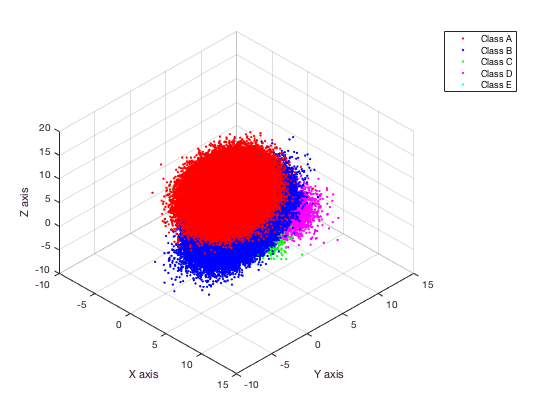

rotx = @(t) [1 0 0; 0 cosd(t) -sind(t) ; 0 sind(t) cosd(t)] ;
roty = @(t) [cosd(t) 0 sind(t) ; 0 1 0 ; -sind(t) 0  cosd(t)] ;
rotz = @(t) [cosd(t) -sind(t) 0 ; sind(t) cosd(t) 0 ; 0 0 1] ;
%creating class A
Q = rotx(20)*roty(30)*rotz(20);
sigma_A = Q*diag([2 3.5 6])*Q';
mu_A = [1 3 5];
data_A = gaussian_data(750000,3,mu_A,sigma_A);

%creating class B
Q = rotx(15)*roty(20)*rotz(15);
sigma_B = Q*diag([2 7 2.5])*Q';
mu_B = [3 2.2 2.5];
data_B = gaussian_data(190000,3,mu_B,sigma_B);

%creating class C
Q = rotx(3)*roty(6)*rotz(12);
sigma_C = Q*diag([3 0.5 2.2])*Q';
mu_C = [2.1 2.2 0.3];
data_C = gaussian_data(45000,3,mu_C,sigma_C);

%creating class D
Q = rotx(54)*roty(67.5)*rotz(33);
sigma_D = Q*diag([2.25 1.7 3.75])*Q';
mu_D = [4 6.2 2];
data_D = gaussian_data(12000,3,mu_D,sigma_D);

%creating class E
Q = rotx(73)*roty(46)*rotz(81);
sigma_E = Q*diag([1.33 0.2 0.15])*Q';
mu_E = [3 2.5 -1 ];
data_E = gaussian_data(3000,3,mu_E,sigma_E);

%VISUALIZE
figure(1);  
plot3(data_A(:,1),data_A(:,2),data_A(:,3),'color','r','Marker','.','LineStyle','none')
hold on;
plot3(data_B(:,1),data_B(:,2),data_B(:,3),'color','b','Marker','.','LineStyle','none')
plot3(data_C(:,1),data_C(:,2),data_C(:,3),'color','g','Marker','.','LineStyle','none')
plot3(data_D(:,1),data_D(:,2),data_D(:,3),'color','m','Marker','.','LineStyle','none')
plot3(data_E(:,1),data_E(:,2),data_E(:,3),'color','c','Marker','.','LineStyle','none')
zlabel('Z axis');
% Create ylabel
ylabel('Y axis');
% Create xlabel
xlabel('X axis');
view([45 45]);
h = findobj('Color','r');
g = findobj('Color','b');
i = findobj('Color','g');
j = findobj('Color','m');
l = findobj('Color','c');
v = [h(1) g(1) i(1) j(1) l(1)];
legend(v,'Class A', 'Class B', 'Class C', 'Class D', 'Class E');
grid on;
hold off

figure(2);
visualize_ellipses(data_A, data_B, data_C, data_D, data_E);

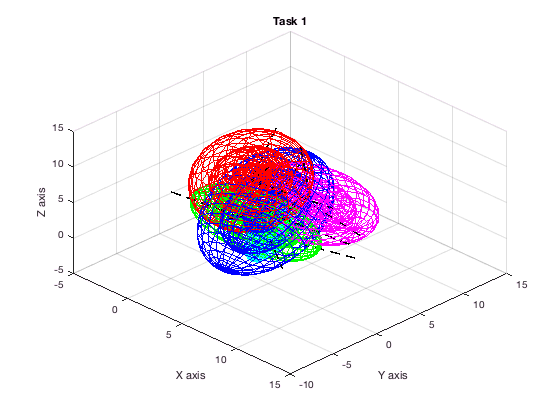

title('Task 1')

**Task 2:** Construct randomly (uniformly) selected training and test data set from the composite of your constructed 5 class data sets, where the training data should constitute 10% of the overall data and the test data the remaining 90% of the data. Record the number of train data samples for each of the training set classes as well as the exact indexes of the training and test data samples. 

Solution:

%random test and train %10 10% shuffle data (sequence uniform max entropy
%mini information) 

% We have to take the 10% from each data shuffle and them combine
data = {data_A ; data_B ; data_C ; data_D ; data_E};
data_labels = {ones(size(data_A,1),1); 2*ones(size(data_B,1),1); 3*ones(size(data_C,1),1) ; 4* ones(size(data_D,1),1) ; 5*ones(size(data_E,1),1)};
data_size = [size(data_A,1) ; size(data_B,1) ; size(data_C,1) ; size(data_D,1) ; size(data_E,1)];
train_fr = 0.10; 
test_fr = 0.90;
rand('state',39)
[train_data, train_labels, test_data, test_labels] = deal(cell(5,1));
%shuffle individual datasets
for i = 1:5
    r = randperm(data_size(i));
    train_data{i} =  data{i}(r(1:train_fr*data_size(i)),:);
    train_labels{i} = data_labels{i}(r(1:train_fr*data_size(i)),:); 
    test_data{i} =  data{i}(r(train_fr*data_size(i)+1:end),:);
    test_labels{i} = data_labels{i}(r(train_fr*data_size(i)+1:end),:);
end 
%now shuffle train and test sets
rand('state',41)
train_data = cell2mat(train_data);
train_labels = cell2mat(train_labels);
train_size = size(train_data,1);
r1 = randperm(train_size);
train_data = train_data(r1(1:train_size),:)

train_data =     2.1541   -0.6587    7.3775
    0.3377    2.8742    5.3323
    0.3215    4.8105    1.9167
   -1.4137    3.2028    5.7052
    2.0634    2.5820    4.9158
   -0.7266    2.8470    3.4014
    2.0423    3.3394    3.8488
   -1.7398    4.2029    5.3730
    1.9374    1.3835    9.2623
    1.3977    1.2649    3.8411


train_labels = train_labels(r1(1:train_size),:)

train_labels =      1
     1
     1
     1
     2
     1
     2
     1
     1
     1



test_data = cell2mat(test_data);
test_labels = cell2mat(test_labels);
test_size = size(test_data,1);
r2 = randperm(test_size);
test_data = test_data(r2(1:test_size),:)

test_data =     1.5233    0.1058    7.9134
    0.4087    4.4023    6.6575
    1.2202    3.2476    5.1612
    0.7335    0.2079    6.2976
    1.2046    4.0870    3.5217
    3.9061    1.5069    8.3939
    3.1313    1.5519    2.8123
    2.7162    0.0868    5.4574
    4.1002    5.4166    0.4787
    1.5331    5.4908    6.6120


test_labels = test_labels(r2(1:test_size),:)

test_labels =      1
     1
     1
     1
     1
     1
     2
     1
     2
     1



% 
% total_size = size(composite_data,1);
% rand('state',39)
% r = randperm(total_size);
% train_size = 0.10; 
% test_size = 0.90;
% train_data = composite_data(r(1:train_size*total_size),:);
% train_label = data_labels(r(1:train_size*total_size),:);
% test_data = composite_data(r(train_size*total_size+1:end),:);
% test_label = data_labels(r(train_size*total_size+1:end),:);

**Task 3: **Use the training data sets to build a Bayes and neural network classifier for this data.

Solution: 

%Bayes Classifier

% Prepare training data and labels
class_A_train = train_data(train_labels==1,:);
mu_A = mean(class_A_train);
sigma_A = cov(class_A_train);

class_B_train = train_data(train_labels==2,:);
mu_B = mean(class_B_train);
sigma_B = cov(class_B_train);

class_C_train = train_data(train_labels==3,:);
mu_C = mean(class_C_train);
sigma_C = cov(class_C_train);

class_D_train = train_data(train_labels==4,:);
mu_D = mean(class_D_train);
sigma_D = cov(class_D_train);

class_E_train = train_data(train_labels==5,:);
mu_E = mean(class_E_train);
sigma_E = cov(class_E_train);

%priori probabilities
pwA = nnz(train_labels==1)/length(train_labels);
pwB = nnz(train_labels==2)/length(train_labels);
pwC = nnz(train_labels==3)/length(train_labels);
pwD = nnz(train_labels==4)/length(train_labels);
pwE = nnz(train_labels==5)/length(train_labels);

%likelihood
pxwA = gaussian_density(mu_A,sigma_A,test_data);
pxwB = gaussian_density(mu_B,sigma_B,test_data);
pxwC = gaussian_density(mu_C,sigma_C,test_data);
pxwD = gaussian_density(mu_D,sigma_D,test_data);
pxwE = gaussian_density(mu_E,sigma_E,test_data);

%evidence
px = pxwA*pwA + pxwB*pwB + pxwC*pwC +  pxwD*pwD + pxwE*pwE; 

%bayes theorem for posteriori
pwAx = (pxwA*pwA)./px;
pwBx = (pxwB*pwB)./px;
pwCx = (pxwC*pwC)./px;
pwDx = (pxwD*pwD)./px;
pwEx = (pxwE*pwE)./px;

%discriminant functions
gA = log(pxwA)+ log(pwA);
gB = log(pxwB)+ log(pwB);
gC = log(pxwC)+ log(pwC);
gD = log(pxwD)+ log(pwD);
gE = log(pxwE)+ log(pwE);

%visualization
[~,class_index] = max([gA gB gC gD gE],[],2);

figure(3)
visualize_points(class_index, test_data);
class_index

class_index =      1
     1
     1
     1
     1
     1
     2
     1
     2
     1


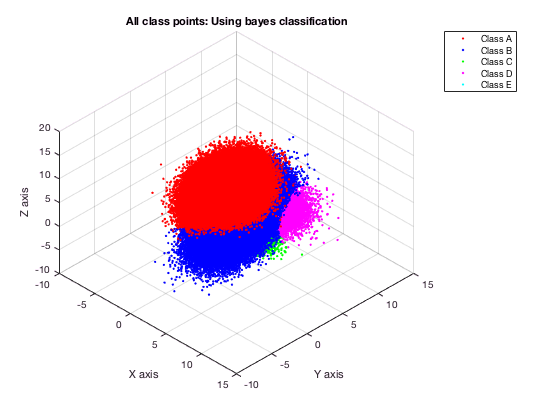

title('All class points: Using bayes classification')
legend('Class A','Class B','Class C', 'Class D', 'Class E')


%Neural network classifier
data_neural = [train_data;test_data];
labels_neural = [train_labels;test_labels];
hidden_layer = 100;
train_test_split = 0.1;
[yind,e,performance,percentErrors] = nn_classifier(data_neural,labels_neural, train_test_split, hidden_layer);

Elapsed time is 31.896774 seconds.



yind

**Task 4: **Apply the testing data to assess the per-class performance of your constructed classifiers.

Solution:

%type 1 and type II errors for each class

%confusion matrix for bayes classifier
C_bayes = confusionmat(test_labels,class_index);
%calculate the classification accuracy for bayes

%confusion matrix for neural network classifier



**Task 5: **Discuss the similarities and differences that the unbalanced data sets have on the in sensitivity and robustness of your constructed classifiers and their training versus test set performances. Which types of classification approaches are more robust to unbalanced data sets (and why?) neural network type approaches or Bayes-like approaches, i.e., nonparametric approaches or parametric approaches?

Solution: 

**Task 6: **Discuss the impacts that taking random draws from unbalanced data sets can have on training sets. For example, what percentage of the possible random (uniform) training set draws would consist of < 10 samples from Class E? What is the probability of such an event as a function of the number of available Class E data samples? 

Solution:

**Task 7: **Compare the performance of your classifiers to a second set of classifiers constructed from balanced training data, i.e., generate balanced perclass data sets and retrain your classifiers.

Solution:

**Task 8: **Unbalanced data sets occur commonly in real-world data analysis problems e.g., in cyber-security normal network traffic events typically outnumber malicious events by many orders of magnitude. Discuss some of the possible approaches that could be applied to address the problem. Note, in general, it may not be possible or feasible to simple collects sufficient data from each representative data class such that the training data with high likelihood is sufficiently balanced.

Solution:

**Task 9: **Can unbalanced data sets be easily identified in real-world data analytics problems (why or why not)?

Solution:

Highly unusual to have balanced data sets. 

function D = gaussian_data_1(K,D,mu,sigma)
    x = randn(K,D); % zero mean and identity covariance;
    
    %Arbitrary specified user covariance needs to be converted in a matrix
    %with specific properties.
    [R,p]=chol(sigma); 
    if p>0
        x=x*sqrtm(sigma);
        sigma_new = sigma;
    else
        x=x*R;
        sigma_new = R;
    end

    D = x + mu; %data with arbitrary specified mean mu and covariance matrix sigma 
    
end 

function f = gaussian_data(K,D,mu,sigma)
    % generate a subset of samples from normal distribution
    N = randn(K,D);
    % centralize the data at zero-mean
    N_c = N - mean(N);
    % obtain eigen values and eigen vectors for covariance of N
    [v,d] = eig(cov(N_c));
    % generate the whitening transform
    R = v*inv(sqrt(d));
    %apply the whitening transform on the centralized data
    W  = N_c*R;
    %obtain eigen values and eigen vectors for given covariance
    [vn,dn] = eig(sigma);
    % generate the inverse whitening transform
    R_inv = sqrt(dn)*inv(vn);
    % apply the inverse whitening transfrom on the whitened gaussian data
    f = W*R_inv;  
    % centralize the data at mu
    f = f + mu;
end 

function axes_plot = visualize_ellipses(data_A, data_B, data_C, data_D, data_E)

    mu_A = mean(data_A);
    mu_B = mean(data_B);
    mu_C = mean(data_C);
    mu_D = mean(data_D);
    mu_E = mean(data_E);

    sigma_A = cov(data_A);
    sigma_B = cov(data_B);
    sigma_C = cov(data_C);
    sigma_D = cov(data_D);
    sigma_E = cov(data_E);
    

    [vA,dA] = eig(sigma_A);
    [vB,dB] = eig(sigma_B);
    [vC,dC] = eig(sigma_C);
    [vD,dD] = eig(sigma_D);
    [vE,dE] = eig(sigma_E);
    axes_plot = axes;
    hold(axes_plot,'on');
    [xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
    surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
    surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
    surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);
    [xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
    surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
    surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
    surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);
    [xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
    surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0);
    surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
    surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);
    [xD1,yD1,zD1,xD2,yD2,zD2,xD3,yD3,zD3] = ellipse_cord(data_D);
    surf(xD1, yD1, zD1,'EdgeColor', 'm','FaceAlpha',0);
    surf(xD2, yD2, zD2, 'EdgeColor', 'm','FaceAlpha',0);
    surf(xD3, yD3, zD3,'EdgeColor', 'm','FaceAlpha',0);
    [xE1,yE1,zE1,xE2,yE2,zE2,xE3,yE3,zE3] = ellipse_cord(data_E);
    surf(xE1, yE1, zE1,'EdgeColor', 'c','FaceAlpha',0);
    surf(xE2, yE2, zE2, 'EdgeColor', 'c','FaceAlpha',0);
    surf(xE3, yE3, zE3,'EdgeColor', 'c','FaceAlpha',0);
    
    h = findobj('Color','r');
    g = findobj('Color','b');
    i = findobj('Color','g');
    j = findobj('Color','m');
    l = findobj('Color','c');
    v = [h(1) g(1) i(1) j(1) l(1)];
    legend(v,'Class A', 'Class B', 'Class C', 'Class D', 'Class E');
%     
%     plot3(data_A(:,1),data_A(:,2),data_A(:,3),'color','r','Marker','.','LineStyle','none')
%     plot3(data_B(:,1),data_B(:,2),data_B(:,3),'color','b','Marker','.','LineStyle','none')
%     plot3(data_C(:,1),data_C(:,2),data_C(:,3),'color','g','Marker','.','LineStyle','none')
%     plot3(data_D(:,1),data_D(:,2),data_D(:,3),'color','m','Marker','.','LineStyle','none')
%     plot3(data_E(:,1),data_E(:,2),data_E(:,3),'color','c','Marker','.','LineStyle','none')
    line([mu_A(1) 7*vA(1,1)+mu_A(1)],[mu_A(2) 7*vA(2,1)+mu_A(2)], [mu_A(3) 7*vA(3,1)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_A(1) 7*vA(1,2)+mu_A(1)],[mu_A(2) 7*vA(2,2)+mu_A(2)], [mu_A(3) 7*vA(3,2)+mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_A(1) 7*vA(1,3)+mu_A(1)],[mu_A(2) 7*vA(2,3)+mu_A(2)], [mu_A(3) 7*vA(3,3)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1); 7*vB(1,1)+ mu_B(1)],[mu_B(2); 7*vB(2,1)+ mu_B(2)], [mu_B(3); 7*vB(3,1)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1) 7*vB(1,2)+ mu_B(1)],[mu_B(2) 7*vB(2,2)+ mu_B(2)], [mu_B(3) 7*vB(3,2)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_B(1) 7*vB(1,3)+ mu_B(1)],[mu_B(2) 7*vB(2,3)+ mu_B(2)], [mu_B(3) 7*vB(3,3)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,1)+mu_C(1)],[mu_C(2) 7*vC(2,1)+mu_C(2)], [mu_C(3) 7*vC(3,1)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,2)+mu_C(1)],[mu_C(2) 7*vC(2,2)+mu_C(2)], [mu_C(3) 7*vC(3,2)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_C(1) 7*vC(1,3)+mu_C(1)],[mu_C(2) 7*vC(2,3)+mu_C(2)], [mu_C(3) 5*vC(3,3)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_D(1) 7*vD(1,1)+mu_D(1)],[mu_D(2) 7*vD(2,1)+mu_D(2)], [mu_D(3) 7*vD(3,1)+mu_D(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_D(1) 7*vD(1,2)+mu_D(1)],[mu_D(2) 7*vD(2,2)+mu_D(2)], [mu_D(3) 7*vD(3,2)+mu_D(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_D(1) 7*vD(1,3)+mu_D(1)],[mu_D(2) 7*vD(2,3)+mu_D(2)], [mu_D(3) 5*vD(3,3)+mu_D(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_E(1) 7*vE(1,1)+mu_E(1)],[mu_E(2) 7*vE(2,1)+mu_E(2)], [mu_E(3) 7*vE(3,1)+mu_E(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_E(1) 7*vE(1,2)+mu_E(1)],[mu_E(2) 7*vE(2,2)+mu_E(2)], [mu_E(3) 7*vE(3,2)+mu_E(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    line([mu_E(1) 7*vE(1,3)+mu_E(1)],[mu_E(2) 7*vE(2,3)+mu_E(2)], [mu_E(3) 5*vE(3,3)+mu_E(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
    %plot decision boundaries
    %plot3(b(:,1),b(:,2),b(:,3),'Marker','.','LineStyle','none','Color','k');
    % Create zlabel
    zlabel('Z axis');

    % Create ylabel
    ylabel('Y axis');

    % Create xlabel
    xlabel('X axis');

    % Create title

    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end

function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    

    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3);

        
end 

function val = gaussian_density(mu,sigma,X)
%finds the gaussian pdf 
    [k,d] = size(X);
    X0 = bsxfun(@minus,X,mu);
    [R,err] = cholcov(sigma,0);
    xRinv = X0 / R;
    % determinant of sigma is product of diagonal elements of cholesky decomposition
    logSqrtDetSigma = sum(log(diag(R))); 
    quadratic = sum(xRinv.^2, 2);
    val = exp(-0.5*quadratic - logSqrtDetSigma - d*log(2*pi)/2);
end 

function axes_plot = visualize_points(class_index,V)
    X = cell(max(class_index),1);
    colors = ['r','b','g','m','c'];
    axes_plot = axes;
    hold(axes_plot,'on');
    for i = 1:max(class_index)
        X{i} = V(class_index == i,:);
        plot3(X{i}(:,1),X{i}(:,2),X{i}(:,3),'Marker','.','LineStyle','none','Color',colors(i));
    end
    xlabel('X axis');
    ylabel('Y axis');
    zlabel('Z axis')
    
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
end

function [yind,e,performance,percentErrors] = nn_classifier(data,targets, train_test_split, hidden_layer)
%train_test_split gives the fraction of training data over the whole data

    target_new = bsxfun(@eq, targets(:), 1:max(targets)); %one hot encoder
    %neural network classifier
    %use nprtool to open the neural network pattern recognition app
    x = data';
    t = target_new';

    % Choose a Training Function
    % For a list of all training functions type: help nntrain
    trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
    
    % Create a Pattern Recognition Network
    hiddenLayerSize = hidden_layer;
    net = patternnet(hiddenLayerSize, trainFcn);

    % % Setup Manual division of Data for Training, Validation, Testing
    net.divideFcn= 'divideind'; % divide the data manually
    net.divideParam.trainInd= 1:train_test_split*(size(x,2)); % training data indices 
    net.divideParam.testInd= train_test_split*(size(x,2))+1:size(x,2);  % testing data indices 

    %decide if you want to show the pop-up window 
    net.trainParam.showWindow = 0;
    nn.trainParam.epoch = 100;
    
    % Train the Network
    [net,tr] = train(net,x,t);

    % Test the Network
    y = net(x(:,net.divideParam.testInd));
    e = gsubtract(t(net.divideParam.testInd),y);
    performance = perform(net,t(net.divideParam.testInd),y);
    tind = vec2ind(t(net.divideParam.testInd));
    yind = vec2ind(y);
    %y = round(y);
    percentErrors = sum(tind ~= yind)/numel(tind);
end 